### **Иван Шаламов, 551 группа. Лабораторная работа № 5.2, 2020.**

clc;
close all;
clear;
opengl software;

### **Практическая часть (1).**

disp('Нагрев тела, изготовленного из металла.');

Нагрев тела, изготовленного из металла.


Ввод начальных параметров.

TextSize = 15;

% Характеристики материала:

% lambda = 0.30; % теплопроводность материала стенки, Вт/(м*К)
% c = 600; % теплоемкость материала стенки, Дж/(кг*К)
% rho = 1800; % плотность материала стенки, кг/м^3
% a = lambda / (rho * c); % коэффициент температуропроводности
% alpha = 1000; % коэффициент теплоотдачи, Вт/(м^2*К)
% T_init = 300; % начальная температура стенки, К
% T_gaz = 2600; % температура потока, К
% delta_mm = 20; % толщина стенки, мм
% delta = delta_mm * 1e-3; % толщина стенки, м
% 
% t_fin = 100; % продолжительность нагрева, с
% time_steps = 50; % количество шагов по времени
% N = 200; % количество узлов сетки
% dh = delta / (N - 1); % шаг по пространству
% dt = t_fin / time_steps; % шаг по времени

lambda = 20; % теплопроводность материала стенки, Вт/(м*К)
c = 300; % теплоемкость материала стенки, Дж/(кг*К)
rho = 7800; % плотность материала стенки, кг/м^3
a = lambda / (rho * c); % коэффициент температуропроводности
alpha = 4000; % коэффициент теплоотдачи, Вт/(м^2*К)
T_init = 300; % начальная температура стенки, К
T_gaz = 2600; % температура потока, К
delta_mm = 4; % толщина стенки, мм
delta = delta_mm * 1e-3; % толщина стенки, м

t_fin = 2; % продолжительность нагрева, с
time_steps = 50; % количество шагов по времени
N = 200; % количество узлов сетки
dh = delta / (N - 1); % шаг по пространству
dt = t_fin / time_steps; % шаг по времени

Назначение узлов сетки.

x = 0:dh:delta; % сетка по x

Решение неявной схемой (первая аппроксимация граничных условий). Абсолютная устойчивость. Порядок аппроксимации: O(t, h^2).

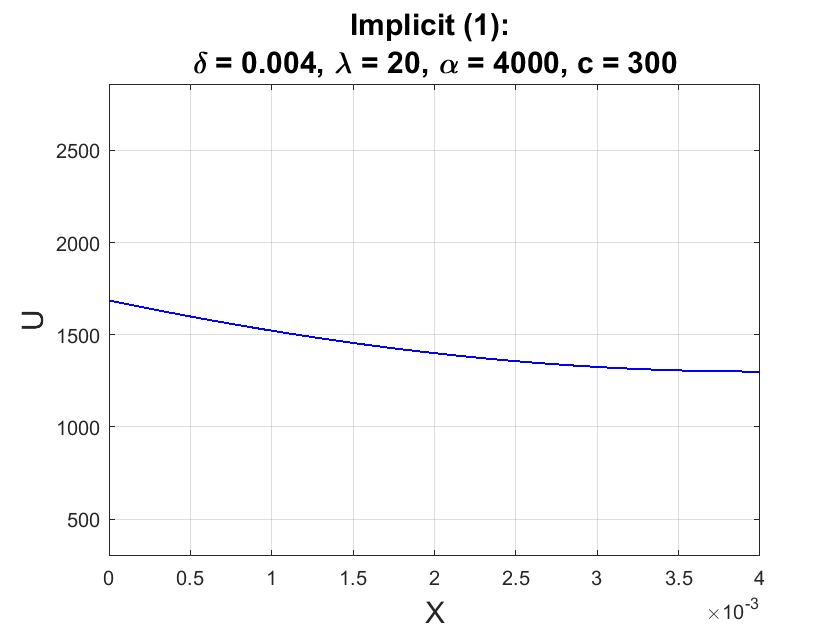

[Uimpl1, q_impl1, t_i1] = Implicit1(x, lambda, c, a, alpha, T_init, T_gaz, delta, ...
    t_fin, N, dh, dt, TextSize);

### **Исследовательская часть (1).**

Решение неявной схемой (вторая аппроксимация граничных условий). Абсолютная устойчивость. Порядок аппроксимации: O(t, h^2).

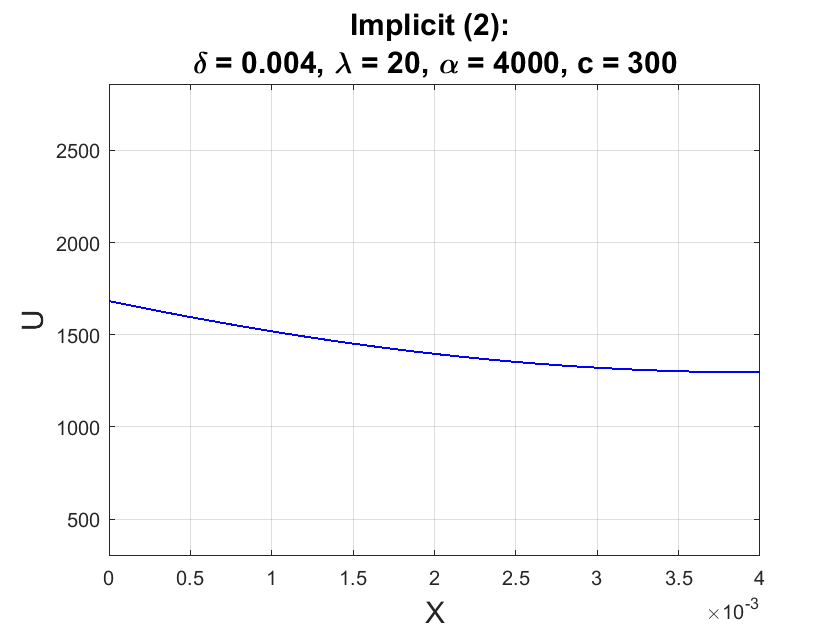

[Uimpl2, q_impl2, t_i2] = Implicit2(x, lambda, c, a, alpha, T_init, T_gaz, delta, ...
    t_fin, N, dh, dt, TextSize);

Решение схемой Кранка — Николсона (первая аппроксимация граничных условий). Абсолютная устойчивость. Порядок аппроксимации: O(t^2, h^2).

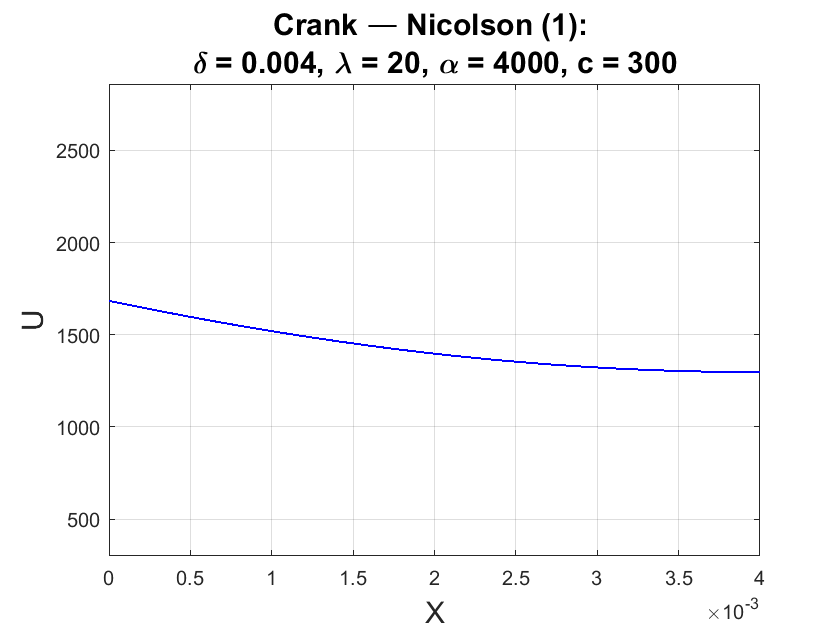

[Ucn1, q_cn1, t_cn1] = CrankNicolson1(x, lambda, c, a, alpha, T_init, T_gaz, delta, ...
    t_fin, N, dh, dt, TextSize);

Решение схемой Кранка — Николсона (вторая аппроксимация граничных условий). Абсолютная устойчивость. Порядок аппроксимации: O(t^2, h^2).

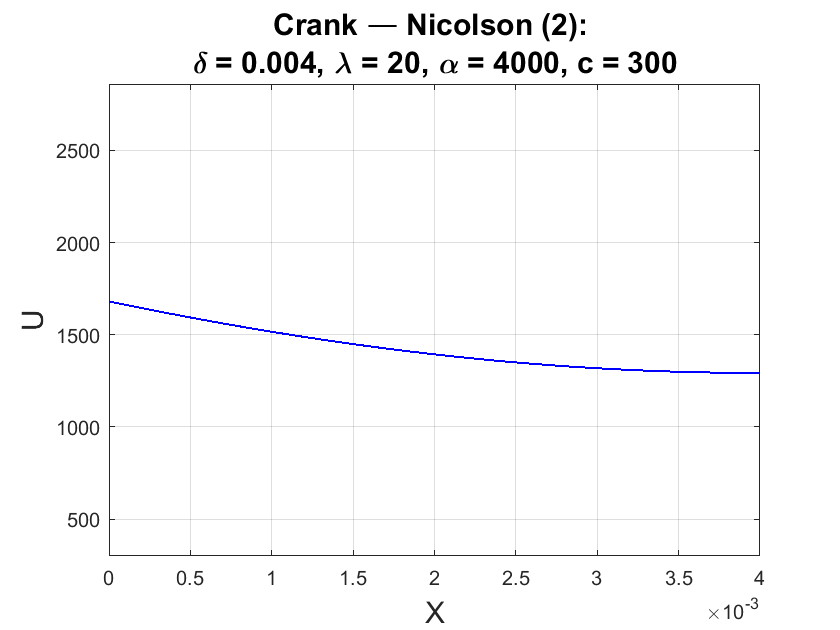

[Ucn2, q_cn2, t_cn2] = CrankNicolson2(x, lambda, c, a, alpha, T_init, T_gaz, delta, ...
    t_fin, N, dh, dt, TextSize);

Решение схемой Рихтмайера — Мортона (первая аппроксимация граничных условий). Абсолютная устойчивость. Порядок аппроксимации при θ = 0.5: O(t^2, h^2), при θ = 0.5 + h^2 / (12 * a * t): O(t^2, h^4).

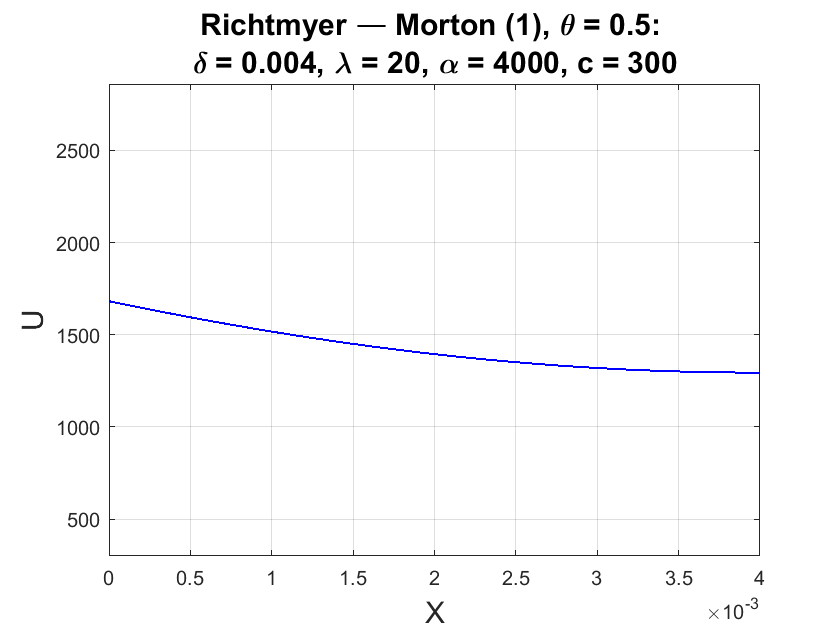

theta = 0.5;

[Urm1, q_rm1, t_rm1] = RichtmyerMorton1(x, lambda, c, a, alpha, T_init, T_gaz, delta, ...
    t_fin, N, dh, dt, theta, TextSize);

Решение схемой Рихтмайера — Мортона (вторая аппроксимация граничных условий). Абсолютная устойчивость. Порядок аппроксимации при θ = 0.5: O(t^2, h^2), при θ = 0.5 + h^2 / (12 * a * t): O(t^2, h^4).

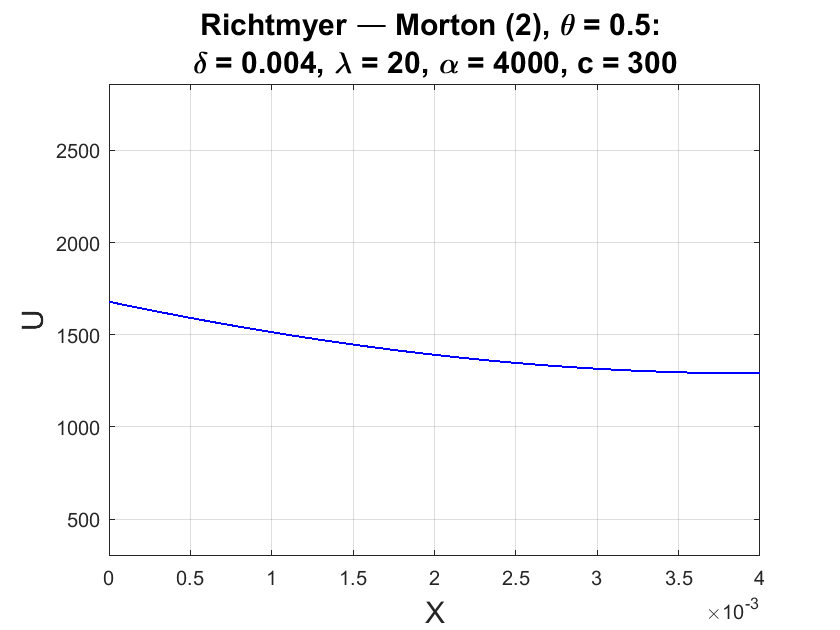

[Urm2, q_rm2, t_rm2] = RichtmyerMorton2(x, lambda, c, a, alpha, T_init, T_gaz, delta, ...
    t_fin, N, dh, dt, theta, TextSize);

Решение схемой Рихтмайера — Мортона (первая аппроксимация граничных условий). Абсолютная устойчивость. Порядок аппроксимации при θ = 0.5: O(t^2, h^2), при θ = 0.5 + h^2 / (12 * a * t): O(t^2, h^4).

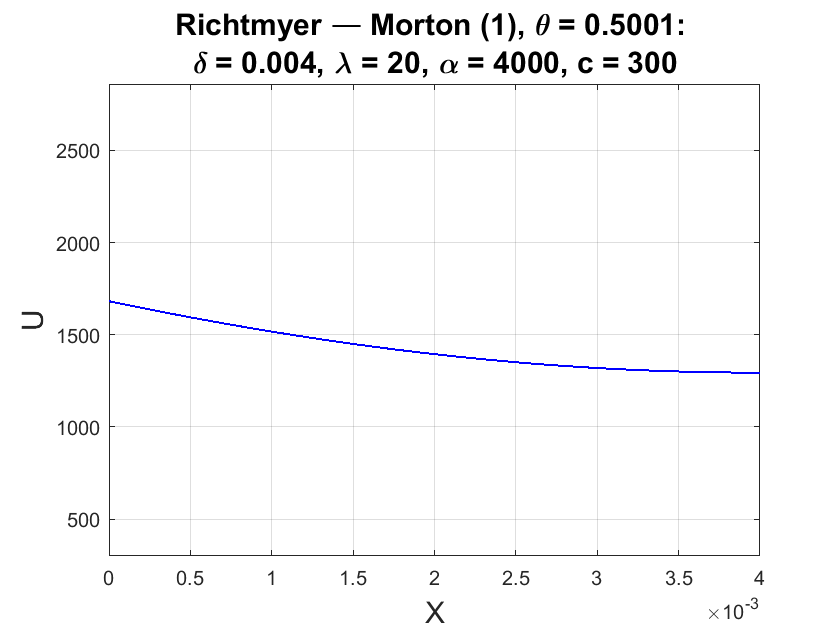

theta = 0.5 + dh^2 / (12 * a * dt);

[Urm3, q_rm3, t_rm3] = RichtmyerMorton1(x, lambda, c, a, alpha, T_init, T_gaz, delta, ...
    t_fin, N, dh, dt, theta, TextSize);

Решение схемой Рихтмайера — Мортона (вторая аппроксимация граничных условий). Абсолютная устойчивость. Порядок аппроксимации при θ = 0.5: O(t^2, h^2), при θ = 0.5 + h^2 / (12 * a * t): O(t^2, h^4).

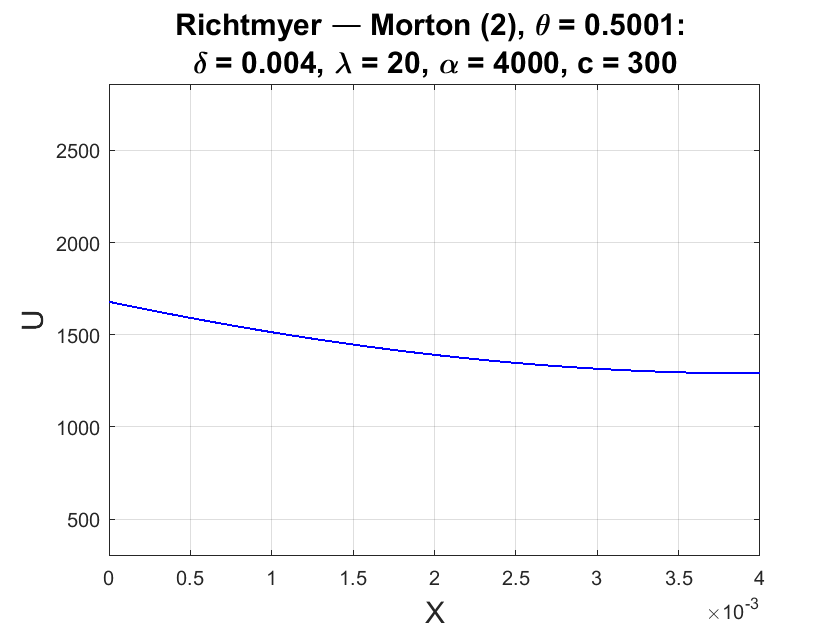

[Urm4, q_rm4, t_rm4] = RichtmyerMorton2(x, lambda, c, a, alpha, T_init, T_gaz, delta, ...
    t_fin, N, dh, dt, theta, TextSize);

Вывод теплового потока для различных схем.

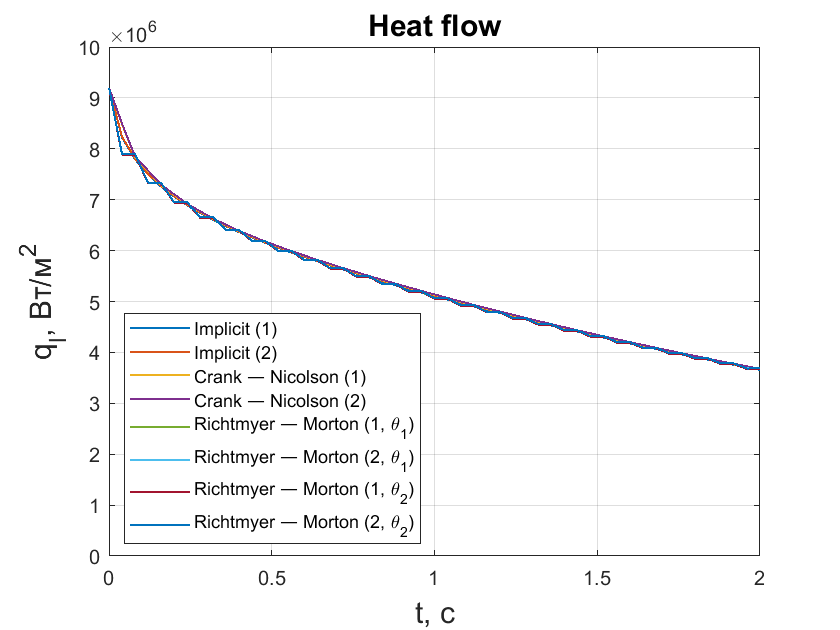

plot(t_i1, q_impl1, t_i2, q_impl2, t_cn1, q_cn1, t_cn2, q_cn2, ...
    t_rm1, q_rm1, t_rm2, q_rm2, t_rm3, q_rm3, t_rm4, q_rm4, 'LineWidth', 1);
grid on;
title('Heat flow', 'FontSize', TextSize);
xlabel('t, с', 'FontSize', TextSize);
ylabel('q_l, Вт/м^2', 'FontSize', TextSize);
axis([0, t_fin, 0, 10e6]);
legend({'Implicit (1)', 'Implicit (2)', 'Crank — Nicolson (1)', ...
    'Crank — Nicolson (2)', 'Richtmyer — Morton (1, \theta_1)', ...
    'Richtmyer — Morton (2, \theta_1)', 'Richtmyer — Morton (1, \theta_2)', ...
    'Richtmyer — Morton (2, \theta_2)'}, 'Location', 'best');

### **Практическая часть (2).**

disp('Нагрев тела, изготовленного из малотеплопроводного материала.');

Нагрев тела, изготовленного из малотеплопроводного материала.


Ввод начальных параметров.

% Характеристики материала:

lambda = 0.2; % теплопроводность материала стенки, Вт/(м*К)
c = 800; % теплоемкость материала стенки, Дж/(кг*К)
rho = 2000; % плотность материала стенки, кг/м^3
a = lambda / (rho * c); % коэффициент температуропроводности
alpha = 4000; % коэффициент теплоотдачи, Вт/(м^2*К)
T_init = 300; % начальная температура стенки, К
T_gaz = 2600; % температура потока, К
delta_mm = 4; % толщина стенки, мм
delta = delta_mm * 1e-3; % толщина стенки, м

t_fin = 2; % продолжительность нагрева, с
time_steps = 50; % количество шагов по времени
N = 200; % количество узлов сетки
dh = delta / (N - 1); % шаг по пространству
dt = t_fin / time_steps; % шаг по времени

Назначение узлов сетки.

x = 0:dh:delta; % сетка по x

Решение неявной схемой (первая аппроксимация граничных условий). Абсолютная устойчивость. Порядок аппроксимации: O(t, h^2).

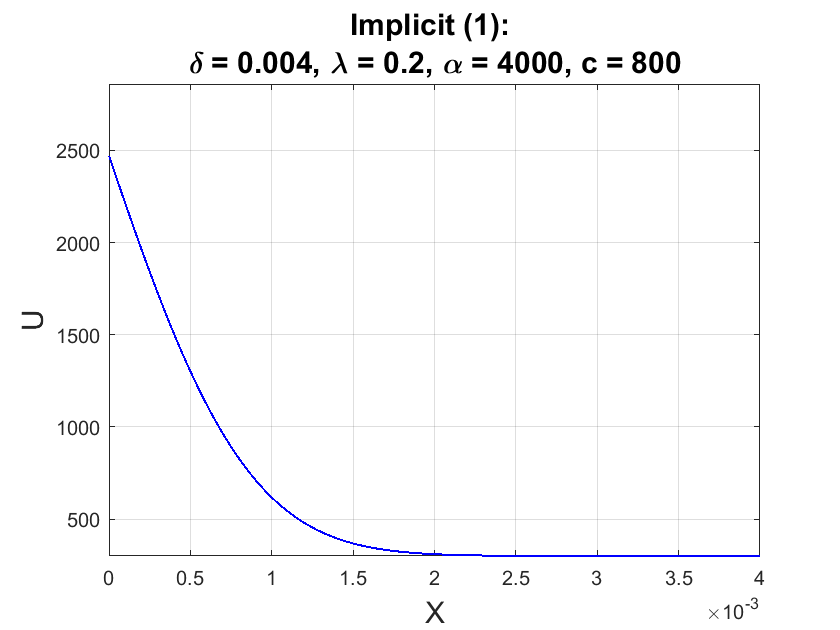

[Uimpl1, q_impl1, t_i1] = Implicit1(x, lambda, c, a, alpha, T_init, T_gaz, delta, ...
    t_fin, N, dh, dt, TextSize);

### **Исследовательская часть (2).**

Решение неявной схемой (вторая аппроксимация граничных условий). Абсолютная устойчивость. Порядок аппроксимации: O(t, h^2).

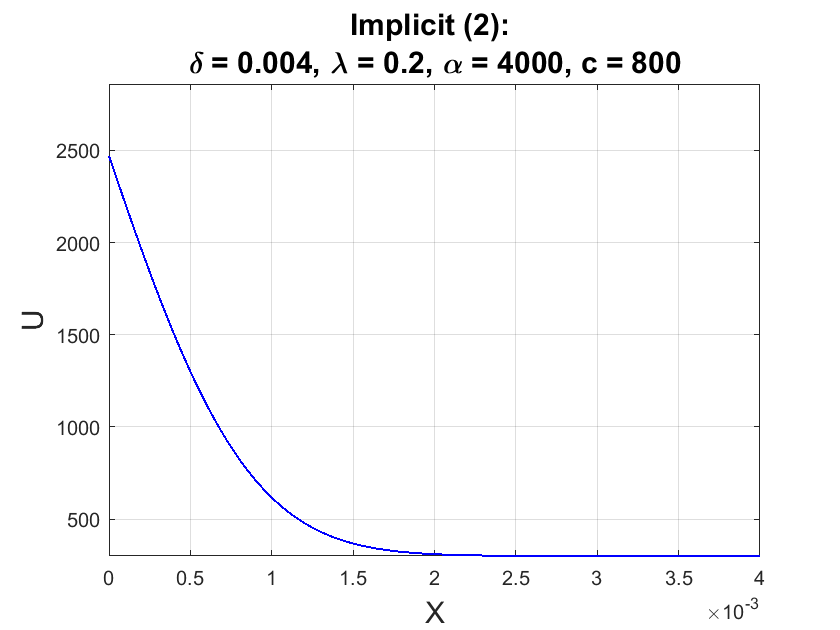

[Uimpl2, q_impl2, t_i2] = Implicit2(x, lambda, c, a, alpha, T_init, T_gaz, delta, ...
    t_fin, N, dh, dt, TextSize);

Решение схемой Кранка — Николсона (первая аппроксимация граничных условий). Абсолютная устойчивость. Порядок аппроксимации: O(t^2, h^2).

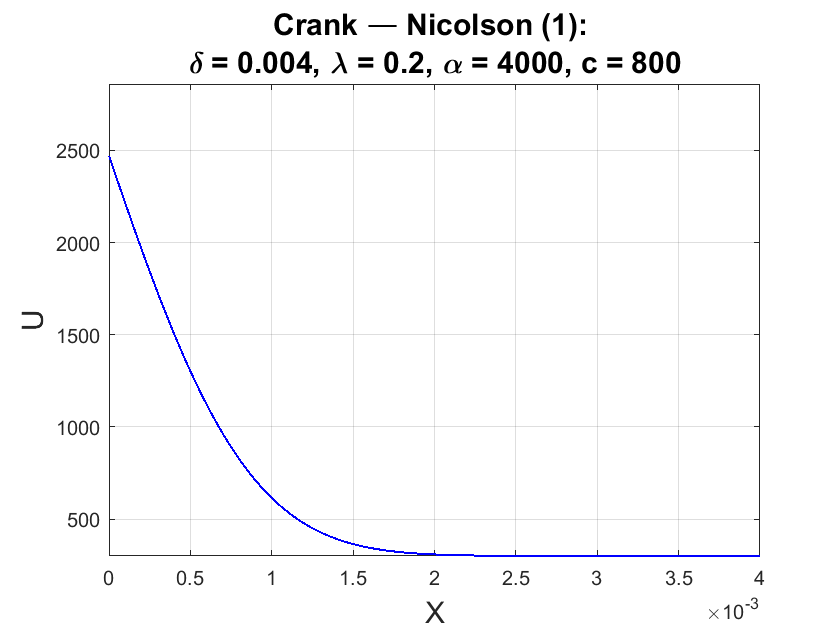

[Ucn1, q_cn1, t_cn1] = CrankNicolson1(x, lambda, c, a, alpha, T_init, T_gaz, delta, ...
    t_fin, N, dh, dt, TextSize);

Решение схемой Кранка — Николсона (вторая аппроксимация граничных условий). Абсолютная устойчивость. Порядок аппроксимации: O(t^2, h^2).

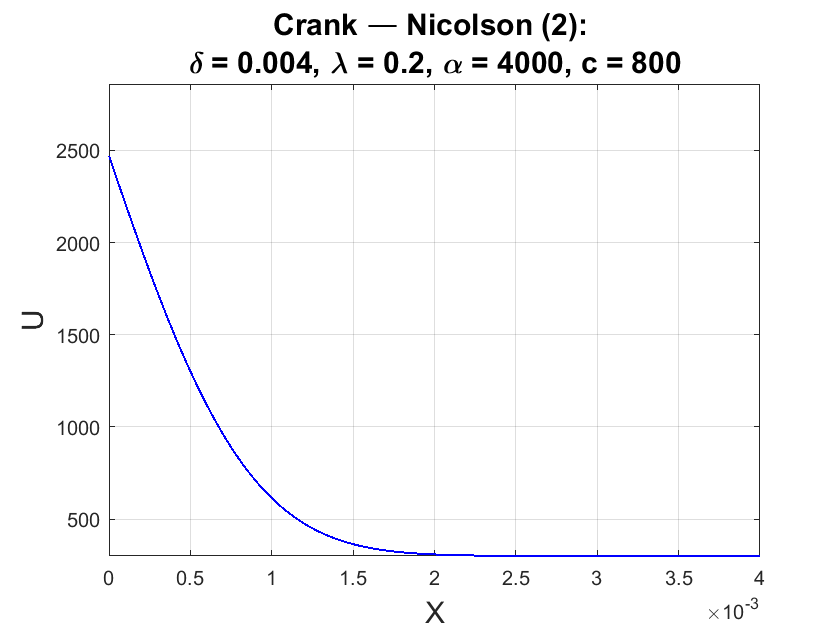

[Ucn2, q_cn2, t_cn2] = CrankNicolson2(x, lambda, c, a, alpha, T_init, T_gaz, delta, ...
    t_fin, N, dh, dt, TextSize);

Решение схемой Рихтмайера — Мортона (первая аппроксимация граничных условий). Абсолютная устойчивость. Порядок аппроксимации при θ = 0.5: O(t^2, h^2), при θ = 0.5 + h^2 / (12 * a * t): O(t^2, h^4).

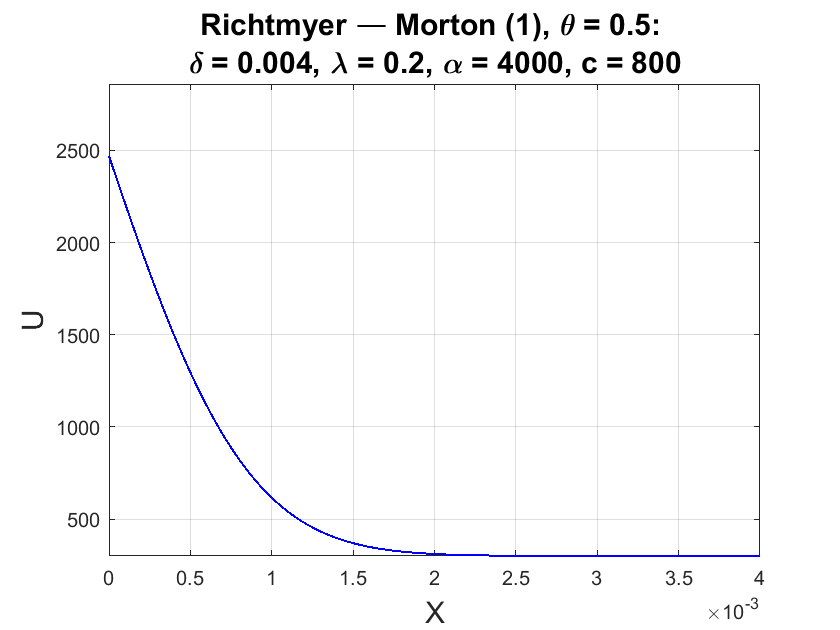

theta = 0.5;

[Urm1, q_rm1, t_rm1] = RichtmyerMorton1(x, lambda, c, a, alpha, T_init, T_gaz, delta, ...
    t_fin, N, dh, dt, theta, TextSize);

Решение схемой Рихтмайера — Мортона (вторая аппроксимация граничных условий). Абсолютная устойчивость. Порядок аппроксимации при θ = 0.5: O(t^2, h^2), при θ = 0.5 + h^2 / (12 * a * t): O(t^2, h^4).

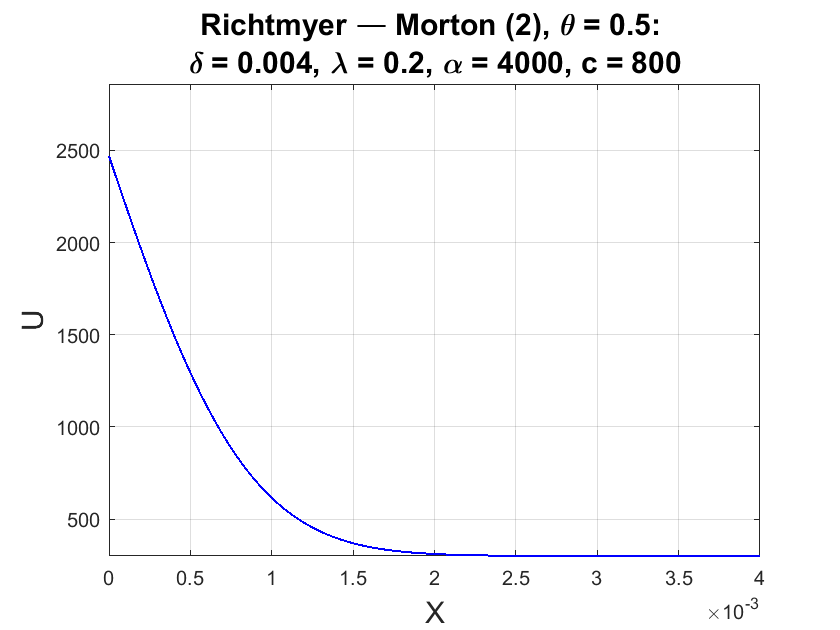

[Urm2, q_rm2, t_rm2] = RichtmyerMorton2(x, lambda, c, a, alpha, T_init, T_gaz, delta, ...
    t_fin, N, dh, dt, theta, TextSize);

Решение схемой Рихтмайера — Мортона (первая аппроксимация граничных условий). Абсолютная устойчивость. Порядок аппроксимации при θ = 0.5: O(t^2, h^2), при θ = 0.5 + h^2 / (12 * a * t): O(t^2, h^4).

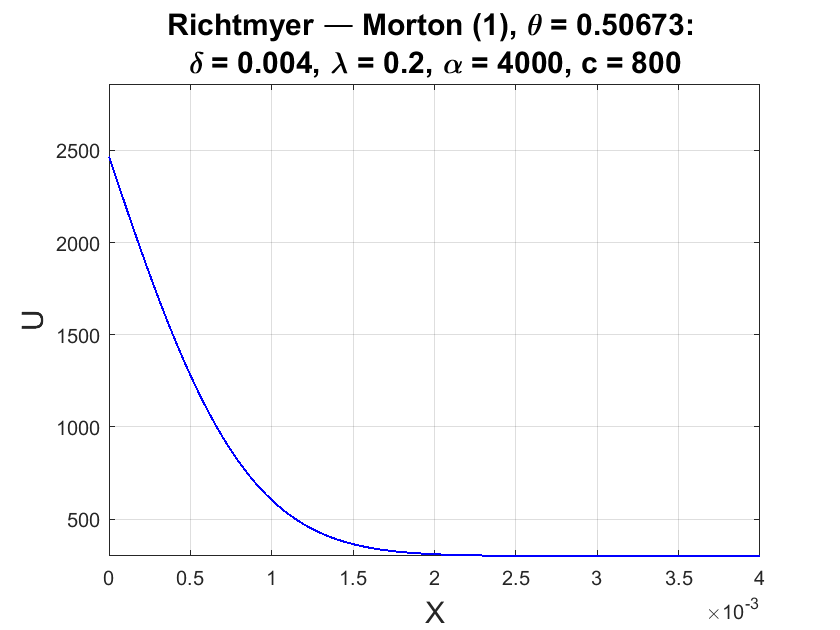

theta = 0.5 + dh^2 / (12 * a * dt);

[Urm3, q_rm3, t_rm3] = RichtmyerMorton1(x, lambda, c, a, alpha, T_init, T_gaz, delta, ...
    t_fin, N, dh, dt, theta, TextSize);

Решение схемой Рихтмайера — Мортона (вторая аппроксимация граничных условий). Абсолютная устойчивость. Порядок аппроксимации при θ = 0.5: O(t^2, h^2), при θ = 0.5 + h^2 / (12 * a * t): O(t^2, h^4).

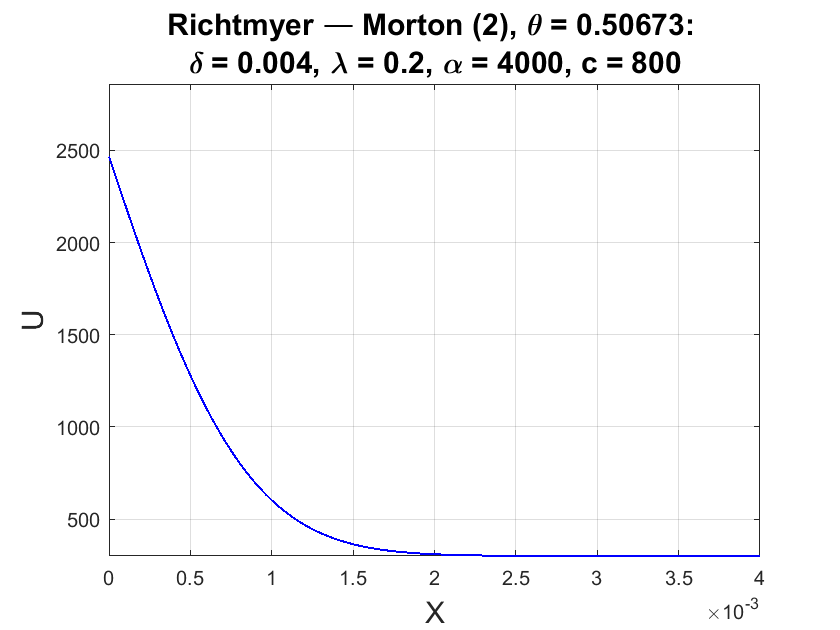

[Urm4, q_rm4, t_rm4] = RichtmyerMorton2(x, lambda, c, a, alpha, T_init, T_gaz, delta, ...
    t_fin, N, dh, dt, theta, TextSize);

Вывод теплового потока для различных схем.

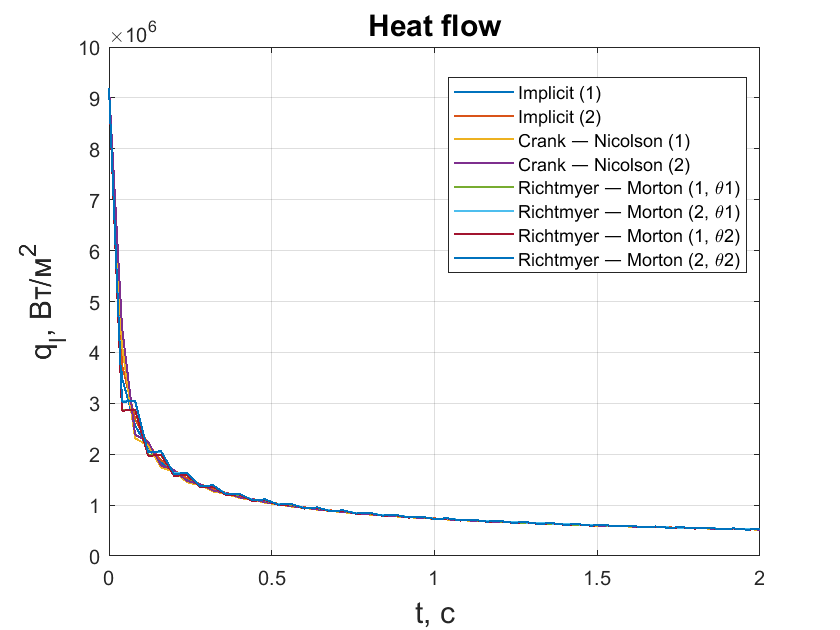

plot(t_i1, q_impl1, t_i2, q_impl2, t_cn1, q_cn1, t_cn2, q_cn2, ...
    t_rm1, q_rm1, t_rm2, q_rm2, t_rm3, q_rm3, t_rm4, q_rm4, 'LineWidth', 1);
grid on;
title('Heat flow', 'FontSize', TextSize);
xlabel('t, с', 'FontSize', TextSize);
ylabel('q_l, Вт/м^2', 'FontSize', TextSize);
axis([0, t_fin, 0, 10e6]);
legend({'Implicit (1)', 'Implicit (2)', 'Crank — Nicolson (1)', ...
    'Crank — Nicolson (2)', 'Richtmyer — Morton (1, \theta1)', ...
    'Richtmyer — Morton (2, \theta1)', 'Richtmyer — Morton (1, \theta2)', ...
    'Richtmyer — Morton (2, \theta2)'}, 'Location', 'best');

### **Использованные функции.**

Неявная схема. Метод прогонки. Первая аппроксимация граничных условий.

function [Uold, q_l, t] = Implicit1(x, lambda, c, a, alpha, T_init, T_gaz, delta, ...
        t_fin, N, dh, dt, TextSize)
    
    % Начальные условия:
    Uold = T_init * ones(1, N);
    Unew = Uold;
    i = 1;
    t(i) = 0;
    q_l(i) = abs(alpha * (T_gaz - Uold(1)));
    
    % Коэффициенты разностной схемы:
    A = 1;
    B = 1 + dh^2 / (2 * dt * a);
    C = 1;
    Bi = alpha * dh / lambda; % кооэффициент Био (безразмерный коэффициент теплоотдачи)
    
    while t(i) <= t_fin
        
        % Начальные значения векторов прогоночных коэффициентов:
        
        K = zeros(1, N-1);
        L = K;
        
        K(1) = 1 / (1 + Bi);
        L(1) = Bi * T_gaz / (1 + Bi);
        
        t(i+1) = t(i) + dt;
        
        % Прямая прогонка:
        
        for j = 2:N-1
            
            K(j) = -1 / (K(j-1) - 2 * B);
            L(j) = (-(dh^2 / (dt * a)) * Uold(j) - L(j-1)) / (K(j-1) - 2 * B);
            
        end
        
        Unew(N) = L(N-1) / (1 - K(N-1));
        
        % Обратная прогонка
        
        for j = N-1:-1:1
            
            Unew(j) = K(j) * Unew(j+1) + L(j);
            
        end
        
        Uold = Unew;
        
        % Вывод графиков:
        plot(x, Unew, 'b', 'LineWidth', 1);
        grid on;
        title(['Implicit (1): ', newline, '\delta = ', num2str(delta), ...
            ', \lambda = ', num2str(lambda), ...
            ', \alpha = ', num2str(alpha), ', c = ', num2str(c)], 'FontSize', TextSize);
        xlabel('X', 'FontSize', TextSize);
        ylabel('U', 'FontSize', TextSize);
        axis([0, delta, T_init, 1.1*T_gaz]);
        pause(0.05);
        
        % Тепловой поток:        
        q_l(i+1) = abs(alpha * (T_gaz - Uold(1)));
        
        i = i + 1;
        
    end
    
end

Схема Кранка — Николсона. Первая аппроксимация граничных условий.

function [Uold, q_l, t] = CrankNicolson1(x, lambda, c, a, alpha, T_init, T_gaz, delta, ...
        t_fin, N, dh, dt, TextSize)
    
    % Начальные условия:
    Uold = T_init * ones(1, N);
    i = 1;
    t(i) = 0;
    q_l(i) = abs(alpha * (T_gaz - Uold(1)));
    
    % Коэффициенты разностной схемы:
    Bi = alpha * dh / lambda; % кооэффициент Био (безразмерный коэффициент теплоотдачи)
    LBV = Bi * T_gaz / (1 + Bi); % левое граничное значение
    RBV = 0; % правое граничное значение
    
    A = [ones(1, N-2), -1];
    B = [1, -2*(1+dh^2/(a*dt))*ones(1, N-2), 1];
    C = [-1/(1+Bi), ones(1, N-2)];
    
    M = full(gallery('tridiag', A, B, C));
    
    while t(i) <= t_fin
        
        t(i+1) = t(i) + dt;
        
        D = ([LBV, -1*Uold(1:N-2)+2*(1-dh^2/(a*dt))*Uold(2:N-1)-1*Uold(3:N), RBV])';
        
        Unew =  mldivide(M, D);
        
        Uold = Unew';
        
        % Вывод графиков:
        plot(x, Unew, 'b', 'LineWidth', 1);
        grid on;
        title(['Crank — Nicolson (1): ', newline, '\delta = ', num2str(delta), ...
            ', \lambda = ', num2str(lambda), ...
            ', \alpha = ', num2str(alpha), ', c = ', num2str(c)], 'FontSize', TextSize);
        xlabel('X', 'FontSize', TextSize);
        ylabel('U', 'FontSize', TextSize);
        axis([0, delta, T_init, 1.1*T_gaz]);
        pause(0.05);
        
        % Тепловой поток:
        q_l(i+1) = abs(alpha * (T_gaz - Uold(1)));
        
        i = i + 1;
        
    end
    
end

Схема Рихтмайера — Мортона. Первая аппроксимация граничных условий.

function [Uold2, q_l, t] = RichtmyerMorton1(x, lambda, c, a, alpha, T_init, ...
        T_gaz, delta, t_fin, N, dh, dt, theta, TextSize)
    
    % Начальные условия:
    Uold1 = T_init * ones(1, N);
    Uold2 = Uold1;
    i = 1;
    t(i) = 0;
    q_l(i) = abs(alpha * (T_gaz - Uold2(1)));
    
    % Коэффициенты разностной схемы:
    Bi = alpha * dh / lambda; % кооэффициент Био (безразмерный коэффициент теплоотдачи)
    LBV = Bi * T_gaz / (1 + Bi); % левое граничное значение
    RBV = 0; % правое граничное значение
    
    A = [ones(1, N-2), -1];
    B = [1, -(dh^2/(a*dt))*(1-theta+2*a*dt/dh^2)*ones(1, N-2), 1];
    C = [-1/(1+Bi), ones(1, N-2)];
    
    M = full(gallery('tridiag', A, B, C));
    
    while t(i) <= t_fin
        
        t(i+1) = t(i) + dt;
        
        D = ([LBV, -(dh^2/(a*dt))*(1-2*theta)*Uold2(2:N-1)-...
            theta*(dh^2/(a*dt))*Uold1(2:N-1), RBV])';
        
        Unew = mldivide(M, D);
        
        Uold1 = Uold2;
        Uold2 = Unew';
        
        % Вывод графиков:
        plot(x, Unew, 'b', 'LineWidth', 1);
        grid on;
        title(['Richtmyer — Morton (1), \theta = ', num2str(theta), ': ', newline, ...
            '\delta = ', num2str(delta), ', \lambda = ', num2str(lambda), ...
            ', \alpha = ', num2str(alpha), ', c = ', num2str(c)], 'FontSize', TextSize);
        xlabel('X', 'FontSize', TextSize);
        ylabel('U', 'FontSize', TextSize);
        axis([0, delta, T_init, 1.1*T_gaz]);
        pause(0.05);
        
        % Тепловой поток:
        q_l(i+1) = abs(alpha * (T_gaz - Uold2(1)));
        
        i = i + 1;
        
    end
    
end

Неявная схема. Метод прогонки. Вторая аппроксимация граничных условий.

function [Uold, q_l, t] = Implicit2(x, lambda, c, a, alpha, T_init, T_gaz, delta, ...
        t_fin, N, dh, dt, TextSize)
    
    % Начальные условия:
    Uold = T_init * ones(1, N);
    i = 1;
    t(i) = 0;
    q_l(i) = abs(alpha * (T_gaz - Uold(1)));
    
    % Коэффициенты разностной схемы:
    Bi = alpha * dh / lambda; % кооэффициент Био (безразмерный коэффициент теплоотдачи)
    LBV = 2 * Bi * T_gaz / (3 + 2 * Bi); % левое граничное значение
    RBV = 0; % правое граничное значение
    
    A = [ones(1, N-2), -4/3];
    B = [1, -2*(1+dh^2/(2*a*dt))*ones(1, N-2), 1];
    C = [-4/(3+2*Bi), ones(1, N-2)];
    
    M = full(gallery('tridiag', A, B, C));
    M(1,3) = 1 / (3 + 2 * Bi);
    M(N,N-2) = 1 / 3;
    
    while t(i) <= t_fin
        
        t(i+1) = t(i) + dt;
        
        D = ([LBV, -(dh^2/(a*dt))*Uold(2:N-1), RBV])';
        
        Unew = mldivide(M, D);
        
        Uold = Unew';
        
        % Вывод графиков:
        plot(x, Unew, 'b', 'LineWidth', 1);
        grid on;
        title(['Implicit (2): ', newline, '\delta = ', num2str(delta), ...
            ', \lambda = ', num2str(lambda), ...
            ', \alpha = ', num2str(alpha), ', c = ', num2str(c)], 'FontSize', TextSize);
        xlabel('X', 'FontSize', TextSize);
        ylabel('U', 'FontSize', TextSize);
        axis([0, delta, T_init, 1.1*T_gaz]);
        pause(0.05);
        
        % Тепловой поток:        
        q_l(i+1) = abs(alpha * (T_gaz - Uold(1)));
        
        i = i + 1;
        
    end
    
end

Схема Кранка — Николсона. Вторая аппроксимация граничных условий.

function [Uold, q_l, t] = CrankNicolson2(x, lambda, c, a, alpha, T_init, T_gaz, delta, ...
        t_fin, N, dh, dt, TextSize)
    
    % Начальные условия:
    Uold = T_init * ones(1, N);
    i = 1;
    t(i) = 0;
    q_l(i) = abs(alpha * (T_gaz - Uold(1)));
    
    % Коэффициенты разностной схемы:
    Bi = alpha * dh / lambda; % кооэффициент Био (безразмерный коэффициент теплоотдачи)
    LBV = 2 * Bi * T_gaz / (3 + 2 * Bi); % левое граничное значение
    RBV = 0; % правое граничное значение
    
    A = [ones(1, N-2), -4/3];
    B = [1, -2*(1+dh^2/(a*dt))*ones(1, N-2), 1];
    C = [-4/(3+2*Bi), ones(1, N-2)];
    
    M = full(gallery('tridiag', A, B, C));
    M(1,3) = 1 / (3 + 2 * Bi);
    M(N,N-2) = 1 / 3;
    
    while t(i) <= t_fin
        
        t(i+1) = t(i) + dt;
        
        D = ([LBV, -1*Uold(1:N-2)+2*(1-dh^2/(a*dt))*Uold(2:N-1)-1*Uold(3:N), RBV])';
        
        Unew = mldivide(M, D);
        
        Uold = Unew';
        
        % Вывод графиков:
        plot(x, Unew, 'b', 'LineWidth', 1);
        grid on;
        title(['Crank — Nicolson (2): ', newline, '\delta = ', num2str(delta), ...
            ', \lambda = ', num2str(lambda), ...
            ', \alpha = ', num2str(alpha), ', c = ', num2str(c)], 'FontSize', TextSize);
        xlabel('X', 'FontSize', TextSize);
        ylabel('U', 'FontSize', TextSize);
        axis([0, delta, T_init, 1.1*T_gaz]);
        pause(0.05);
        
        % Тепловой поток:        
        q_l(i+1) = abs(alpha * (T_gaz - Uold(1)));
        
        i = i + 1;
        
    end
    
end

Схема Рихтмайера — Мортона. Вторая аппроксимация граничных условий.

function [Uold2, q_l, t] = RichtmyerMorton2(x, lambda, c, a, alpha, T_init, ...
        T_gaz, delta, t_fin, N, dh, dt, theta, TextSize)
    
    % Начальные условия:
    Uold1 = T_init * ones(1, N);
    Uold2 = Uold1;
    i = 1;
    t(i) = 0;
    q_l(i) = abs(alpha * (T_gaz - Uold2(1)));
    
    % Коэффициенты разностной схемы:
    Bi = alpha * dh / lambda; % кооэффициент Био (безразмерный коэффициент теплоотдачи)
    LBV = 2 * Bi * T_gaz / (3 + 2 * Bi); % левое граничное значение
    RBV = 0; % правое граничное значение
    
    A = [ones(1, N-2), -4/3];
    B = [1, -(dh^2/(a*dt))*(1-theta+2*a*dt/dh^2)*ones(1, N-2), 1];
    C = [-4/(3+2*Bi), ones(1, N-2)];
    
    M = full(gallery('tridiag', A, B, C));
    M(1,3) = 1 / (3 + 2 * Bi);
    M(N,N-2) = 1 / 3;
    
    while t(i) <= t_fin
        
        t(i+1) = t(i) + dt;
        
        D = ([LBV, -(dh^2/(a*dt))*(1-2*theta)*Uold2(2:N-1)-...
            theta*(dh^2/(a*dt))*Uold1(2:N-1), RBV])';
        
        Unew = mldivide(M, D);
        
        Uold1 = Uold2;
        Uold2 = Unew';
        
        % Вывод графиков:
        plot(x, Unew, 'b', 'LineWidth', 1);
        grid on;
        title(['Richtmyer — Morton (2), \theta = ', num2str(theta), ': ', newline, ...
            '\delta = ', num2str(delta), ', \lambda = ', num2str(lambda), ...
            ', \alpha = ', num2str(alpha), ', c = ', num2str(c)], 'FontSize', TextSize);
        xlabel('X', 'FontSize', TextSize);
        ylabel('U', 'FontSize', TextSize);
        axis([0, delta, T_init, 1.1*T_gaz]);
        pause(0.05);
        
        % Тепловой поток:        
        q_l(i+1) = abs(alpha * (T_gaz - Uold2(1)));
        
        i = i + 1;
        
    end
    
end